clf;
clear;

child_D = imread("../materials/child_degraded.tif");
load("../materials/H1&H2.mat");
[M, N] = size(child_D)

M = 812

N = 812

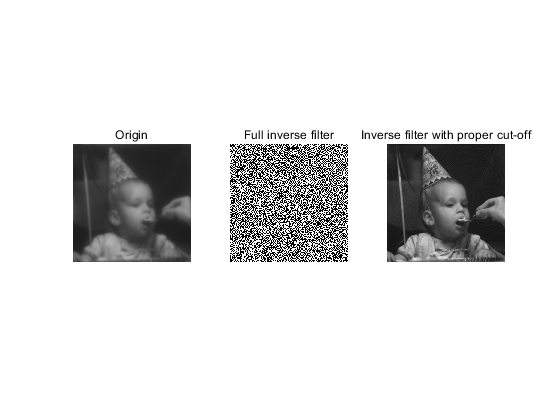


child_F = fftshift(fft2(im2double(im2gray(child_D))));
tmp = zeros(M,N);
cut_off = 100;
for i = 1:M
    for j = 1:N
        if sqrt((i-M/2)^2 + (j-N/2)^2)<cut_off
            tmp(i,j) = child_F(i,j)/H1(i,j);
        end
    end
end

child = real(ifft2(ifftshift(child_F./H1)));
child2 = real(ifft2(ifftshift(tmp)));

subplot(1,3,1);
imshow(child_D);title("Origin");
subplot(1,3,2);
imshow(im2uint8(child));title("Full inverse filter");
subplot(1,3,3);
imshow(im2uint8(child2));title("Inverse filter with proper cut-off");